# **MATLAB Michaelmas Review - Exercises**

In this script, we continue our MATLAB review. But we will now solve exercises to remember some important concepts.

clear all
clc

## Exercise 1

We are given the following random walk process:


$$y_t =y_{t-1} +\varepsilon_t \;$$


where $\varepsilon_t \sim \textrm{IID}\;N\left(0,1\right)$ and $y_0 =\varepsilon_o$.

Let’s use some of the functions from Michaelmas to generate this random walk process: 

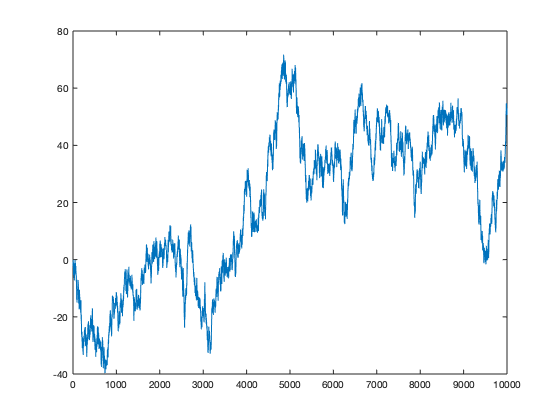

% Using the function "randn" to generate a vector of standard normal random variables:
e = randn(10000,1);
% Now creating the vector y (rw1):
rw1 = zeros(10000,1);
% And start by setting the first element:
rw1(1,1) = e (1,1);
% Doing the loop:
for i=2:numel(rw1)    
    rw1(i,1) = rw1(i-1,1) + e(i,1);   
end
% We finally use the function "plot" to plot y (rw1):
plot(rw1)

Alternatively, we could have used the `cumsum ``function and generated the random walk by:`

help cumsum

 cumsum Cumulative sum of elements.
    Y = cumsum(X) computes the cumulative sum along the first non-singleton
    dimension of X. Y is the same size as X.
  
    Y = cumsum(X,DIM) cumulates along the dimension specified by DIM.
  
    Y = cumsum(___,DIRECTION) cumulates in the direction specified by
    DIRECTION using any of the above syntaxes:
      'forward' - (default) uses the forward direction, from beginning to end.
      'reverse' -           uses the reverse direction, from end to beginning.
 
    Y = cumsum(___,NANFLAG) specifies how NaN (Not-A-Number) values are 
    treated:
 
    'includenan' - (default) the sum of elements containing NaN values is NaN.
    'omitnan'    -           the sum of elements containing NaN values is 
                             the sum of all non-NaN elements. If all 
                             elements are NaN, the result is 0.
 
    Example: 
        X = [

rw2 = cumsum(e);
plot(rw2)

We can finally show that the two methodologies are equivalent:

disp('Difference:')

Difference:


disp(max(max(abs(rw1-rw2))))

     0



## Exercise 2

The first thing we have to do is to load the data and identify the dependent variable and the regressors:

clear all
load FF_Data
head(FFResearchDataFactors)

ans = 8×4 table
    Portfolio    MKT_Factor    SMB_Factor    HML_Factor
    _________    __________    __________    __________

     -0.4119        2.96          -2.3         -2.87   
     -8.7275        2.64          -1.4          4.19   
     -0.2989        0.36         -1.32          0.01   
     -3.7532       -3.24          0.04          0.51   
      6.6476        2.53          -0.2         -0.35   
     -1.9772        2.62         -0.04         -0.02   
     -8.2999       -0.06         -0.56          4.83   
     -0.3049        4.18          -0.1          3.17   


y = FFResearchDataFactors{:,1};
x = FFResearchDataFactors{:,2:4};

### Exercise 2.1

 If we simply want to estimate coefficients of a linear projection, we can use `\ `:

betas = x\y

betas =        1.0746
       1.5306
      0.22224


But we are often interested in other properties of the model and its coefficients. This is why it is useful to have a more complete function (like the `ols_review` function). 

Using the `ols_review `function to estimate these coefficients:

[b,tstat,s2,VCV,VCV_white,R2,R2bar,yhat] = ols_review(y,x,0);
disp(b)

       1.0746
       1.5306
      0.22224



Let's check the `T-Stats` of the coefficients to analyse their significance:

disp('T-Stats')

T-Stats


disp(tstat')

       42.412       36.809       5.9945



They are all highly significant. Now let's check the model's Adjusted $R^2$:

disp('Adjusted R-Squared:')

Adjusted R-Squared:


disp(R2bar)

      0.81893



Although $R^2$s are not the greatest measure of how good a model is, this model seems to be explaining a fair amount of variation in the dependent variable.

### Exercise 2.2

The objective is to replicate the estimation of the parameters above as many times as possible using 60 consecutive months at each time. 

You already saw rolling regressions with both Matthias and Max (Exercise 48). Now let's redo Exercise 48, using the `while` loop rather than the `for` loop. 

But first, lets clear the workspace and reload the data:

load FF_Data
full_y = FFResearchDataFactors{:,1};
full_x = FFResearchDataFactors{:,2:4};

We then just repeat our loop from Exercise 48, but this time using the `while` logic:

size = numel(full_y);
betas = zeros(size-59,3);
i = 1;
while i<=(size-59)
    y = full_y(i:i+59);
    x = full_x(i:i+59, :);
    betas(i,:) = ols_review(y,x,0)';
    %we are only insterested in the first output of the function
    i = i + 1;
end

### Exercise 2.3

The code for this exercise is the same as the one to Exercise 48. The only difference is that here I have replaced the `for` loops by `while` loops in order to keep the same logic from our answer above.

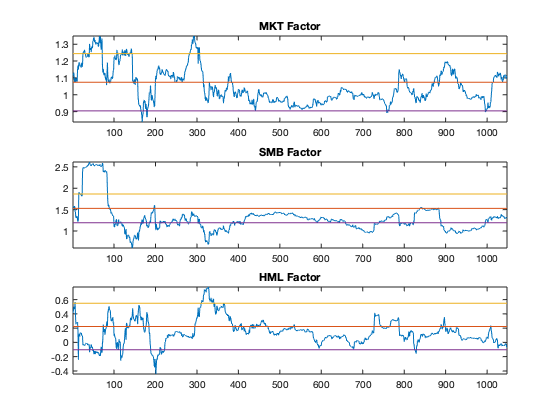

% In order to plot the beta for the full sample, we need to calculate it again:
b = ols_review(full_y,full_x,0);

% We will also need vector of the rolling variances for the rolling betas in order to construct
%the asked "confidence interval". Let's do it in the same way we did for the rolling betas:
vars = zeros(size-59,3);
i = 1;
while i<=(size-59)
    y = full_y(i:i+59);
    x = full_x(i:i+59, :);
    %Now getting White's VCV as the 5th output of our OLS function:
    [~, ~, ~, ~, VCVW] = ols_review(y,x,0); 
    %Then using the elements on the diagonal of the variance covariance 
    %matrix to construct our series of variances:
    vars(i,:) = diag(VCVW)'; 
    i=i+1;
end
%Taking the mean of all vars estimated using 60 months:
var_60 = mean(vars); 

%Plotting the rolling betas and the constants:
titles = {'MKT Factor','SMB Factor','HML Factor'};
i=1;
figure()
while i<=3
    subplot(3,1,i)
    %Creating the "constant" (beta(i) estimated using the full sample): 
    const = ones(length(betas(:,i)), 1) * b(i); 
    %Creating the upper band constant:
    CI_up = const + 1.96 * sqrt(var_60(i)); 
    %Creating the lower band constant:
    CI_down = const - 1.96 * sqrt(var_60(i));
    plot([betas(:,i), const, CI_up, CI_down])
    title(titles{i})
    axis tight
    i=i+1;
end